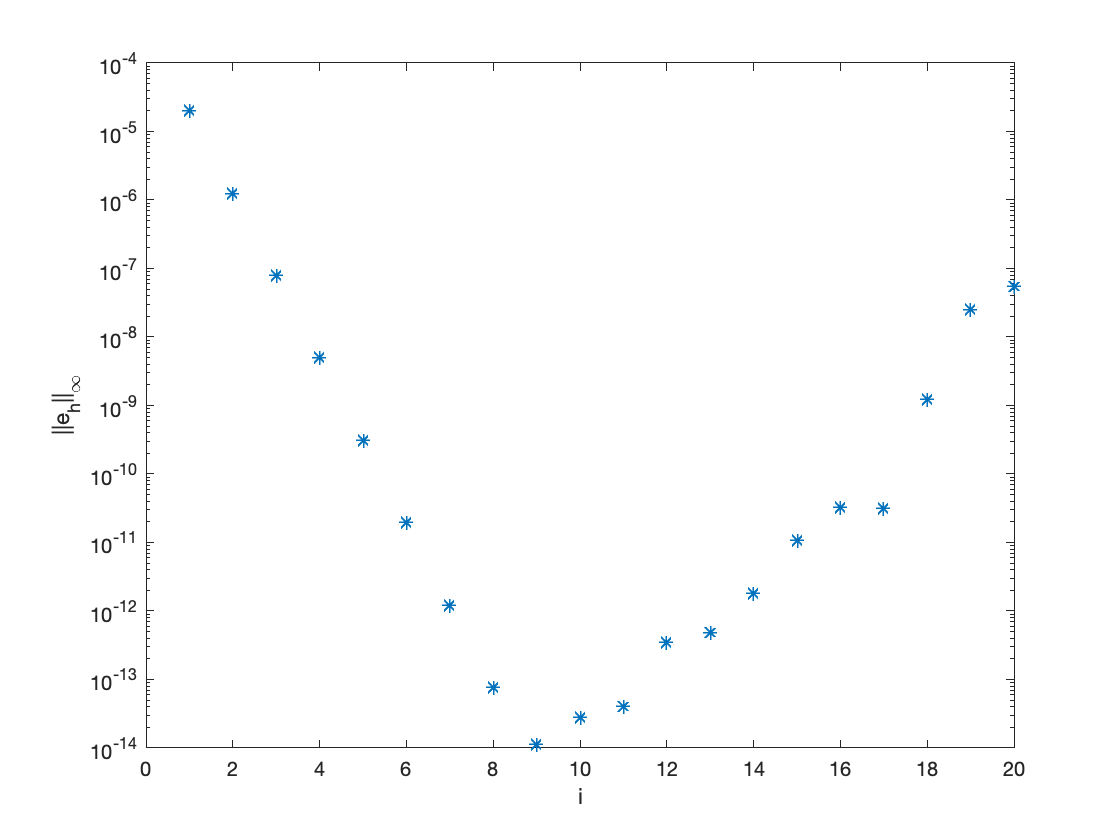

scale factors in each iteration


scale_factor =    15.8820   15.9703   15.9125   15.9754   15.9955   16.0054   15.6459    6.9352    0.3944    0.6904    0.1194    0.7163    0.2649    0.1680    0.3275    1.0380    0.0255    0.0488    0.4694


% Implementation of Mehrstellenverfahren
rhs_f = @(x) exp(-x);
u = @(x) -exp(-x) + (exp(-1)-1)*x + 1;

norms = conv(rhs_f, u, "*");

figure;

function u = solvePoisson1D(A, f)
    %solves the finite-difference system, obtaining the discretized solution
    %to the differential equation
    u = A\f;
        
end

function [A, R] = fdm1D(n)
    % Assemble the finite difference matrices
    h = 1/n; %grid width
    o = ones(n-1, 1);
    % Get A
    A = (1/h^2) * spdiags([-o 2*o -o], [-1 0 1], n-1, n-1); %the total number of grid points is n+1
    % Get R
    R = (1/6) * spdiags([0.5*o 5*o 0.5*o], [0 1 2], n-1, n+1);    
end

function f = rhs(func, R, x)
    % discretize the right-hand side of the equation
    g = func(x);
    f = R*g; 
end

function norms = conv(rhs_f, u_analytic, plot_style)
    
    norms = zeros(1, 20);
    for i = 1:20
        n = 2^i;
        x = (0:(1/n):1)';
        [A, R] = fdm1D(n);
        f = rhs(rhs_f, R, x);
        u_h = solvePoisson1D(A, f);
        u = u_analytic(x(2:end-1));
 
        norms(i) = norm(u - u_h, 'inf');

    end
    semilogy(norms, plot_style, "LineWidth", 1.2);
    ylabel("||e_h||_{\infty}");
    xlabel("i");
    disp('scale factors in each iteration')
    scale_factor = norms(1:end-1)./norms(2:end)
end